Neste arquivo estou testando como ficaria a conversão AD do sinal.

clc;
clear;
micro = 1e-6;
mili = 1e-3;
rad_s = 2*pi;

AD_max = 3.3;
n_bits = 12; % n_bits do conversor A/D

dt = 1e-8; 
tempo_max = 0.010; %em s
t = 0:dt:tempo_max;

Considerando:

- Amplitude maxima de um sinal de EEG em crianças é 1000μV

- Amplitude minima de um sinal de EEG em crianças é 100μV

- Amplitude maxima de um sinal de EEG em adultos é 400μV

- Amplitude minima de um sinal de EEG em adultos é 50μV

- Maior frequencia que um sinal de EEG contem é 70Hz

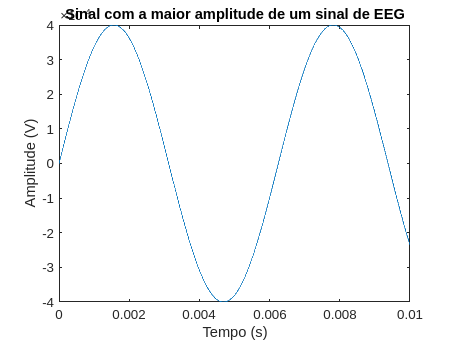

A_max = 400 * micro;
A_min = 50 * micro;
A_med = ((A_max-A_min)/2) + A_min;

A_test1 = 20 * micro;
A_test2 = 10 * micro;
A_test3 = 5 * micro;
A_test4 = 2 * micro;
A_test5 = 1 * micro;

f_max = 160 * rad_s;

% essa margem esta no livro
margem_seg = A_max;

sinal = A_max * sin(f_max * t);
plot(t, sinal);
title('Sinal com a maior amplitude de um sinal de EEG')
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

Colocando uma margem de segurança para leitura igual a metade de A_max

A_seguro = A_max + margem_seg

A_seguro = 8.0000e-04

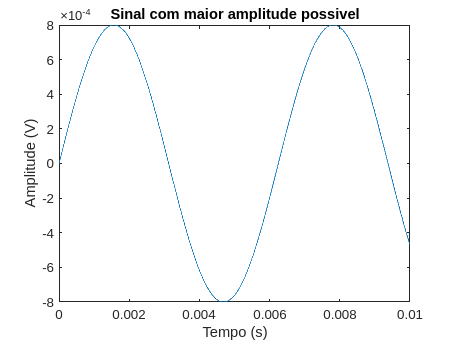


% sinal possuindo a maior amplitude que o sistema é projetado para ler
sinal_max = A_seguro * sin(f_max * t);
plot(t, sinal_max);
title('Sinal com maior amplitude possivel')
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

Para o A/D ser capaz de ler o sinal deve estar entre 0V e 3.3V, então é preciso fazer um offset do sinal e amplificar para esta faixa de valores

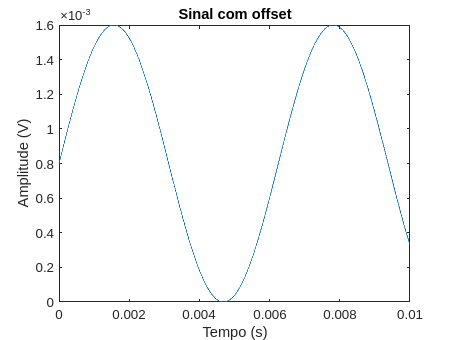

sinal_offset = sinal_max + A_seguro; % A_seguro é o valor de offset
plot(t, sinal_offset);
title('Sinal com offset')
xlabel('Tempo (s)');
ylabel('Amplitude (V)');


% O ganho resultante do amp de instumentação, filtro notch de 60hz,
% offset e amplificador
K = AD_max/max(sinal_offset) % ganho para que a maior amplitude seja 3.3

K = 2.0625e+03

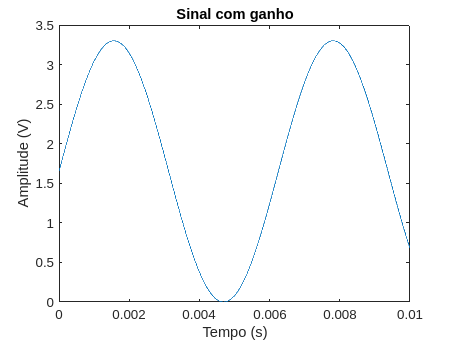

sinal_com_ganho = K * sinal_offset;
plot(t, sinal_com_ganho);
title('Sinal com ganho')
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

Considerando um conversor A/D de n_bits a resolução do sistema será

resolucao = AD_max / ((2^n_bits) - 1);
fprintf('Range: 0 ~ %i\nResolução = %f V/digito', ((2^n_bits) - 1), resolucao);

Range: 0 ~ 4095
Resolução = 0.000806 V/digito

 Tendo o sinal maximo com o ganho para que fique no intervalo 0 ~ AD_max, e junto com a resolução calculada, estarei simulando como ficaria o sinal convertido pelo A/D

Amplitude antes de amplificar: 0.000400 V

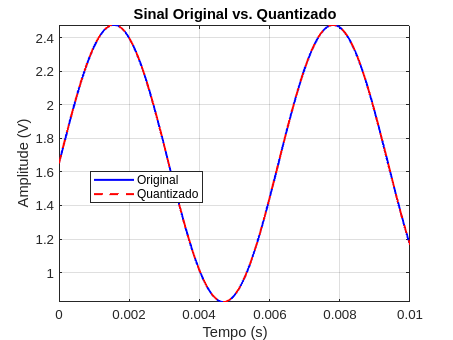

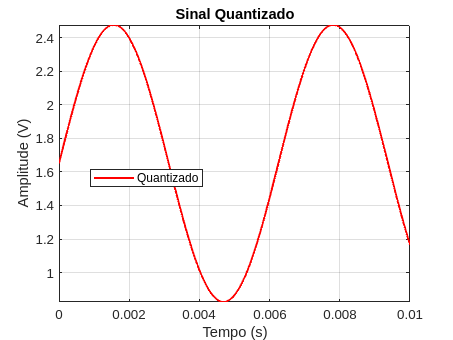

function quantizacao_sinal(amplitude, ganho, frequencia, res, offset, t)

Amplitude antes de amplificar: 0.000225 V

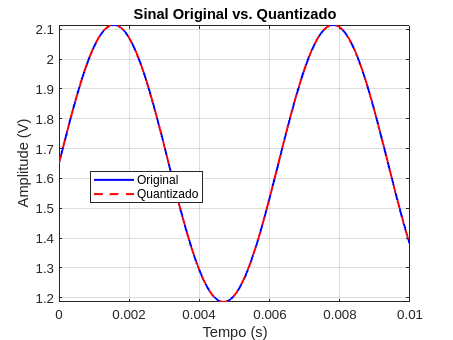

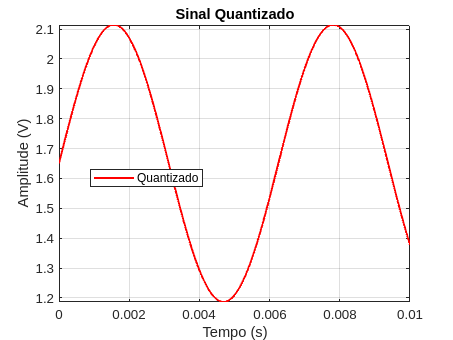

Amplitude antes de amplificar: 0.000050 V

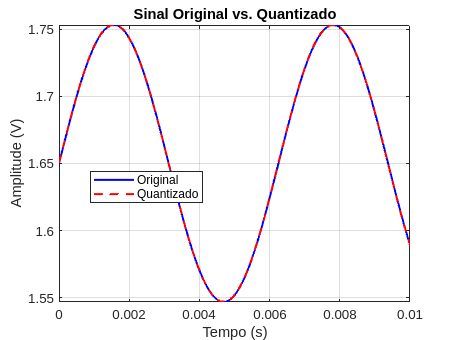

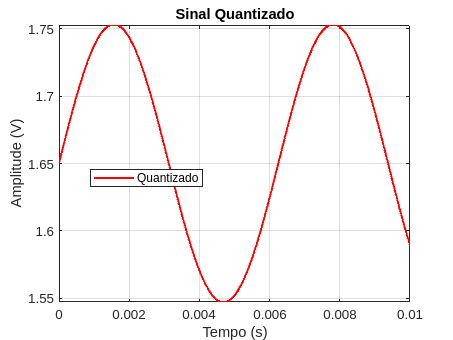

    sinal_com_ganho = (amplitude * sin(frequencia*t) + offset) * ganho ;

Amplitude antes de amplificar: 0.000020 V

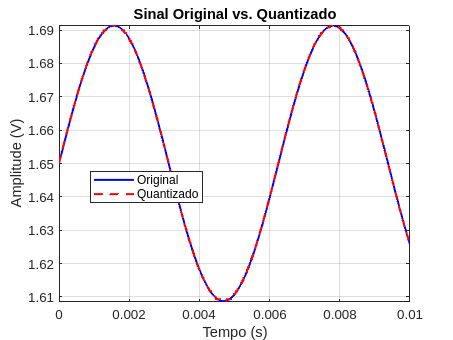

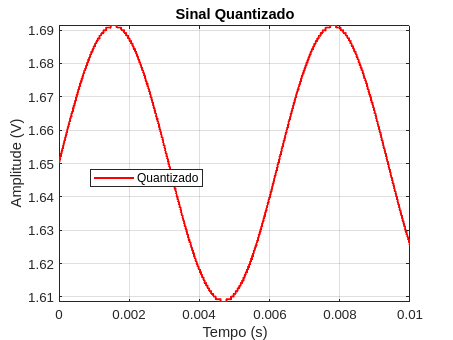

Amplitude antes de amplificar: 0.000010 V

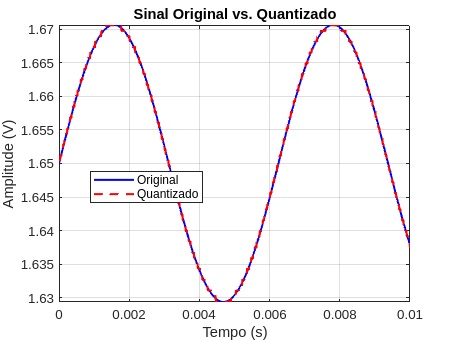

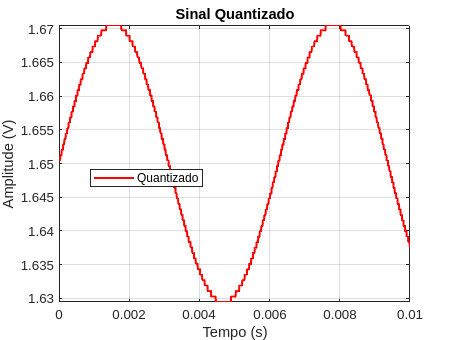

    q_levels = round(sinal_com_ganho / res);
    sinal_quantized = q_levels * res;

Amplitude antes de amplificar: 0.000005 V

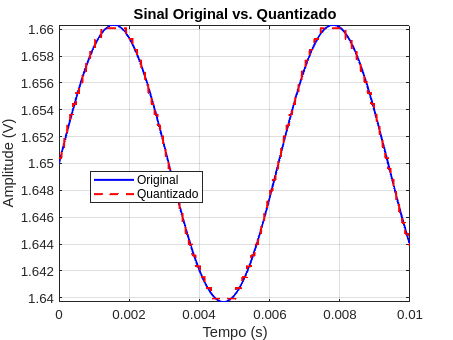

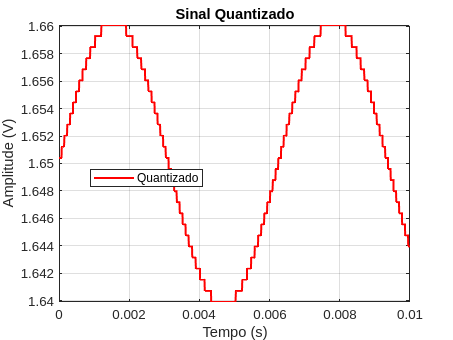

    fprintf('Amplitude antes de amplificar: %f V', amplitude);

Amplitude antes de amplificar: 0.000002 V

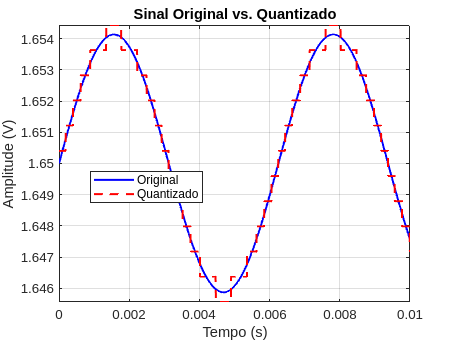

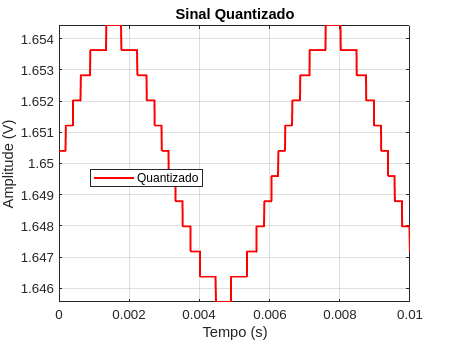

    figure;

Amplitude antes de amplificar: 0.000001 V

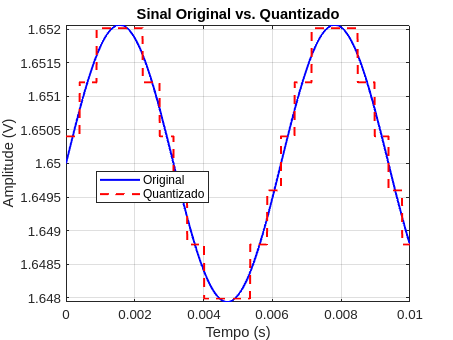

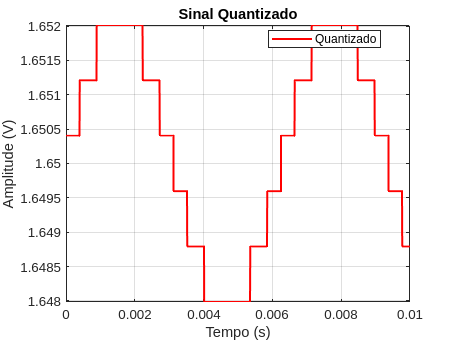

    plot(t, sinal_com_ganho, 'b', t, sinal_quantized, 'r--', 'LineWidth', 1.5);

    title('Sinal Original vs. Quantizado');
    xlabel('Tempo (s)');
    ylabel('Amplitude (V)');
    legend('Original', 'Quantizado', 'Location', 'best');
    grid on;
    axis tight;
    figure;
    plot(t, sinal_quantized, 'r', 'LineWidth', 1.5);
    title('Sinal Quantizado');
    xlabel('Tempo (s)');
    ylabel('Amplitude (V)');
    legend('Quantizado', 'Location', 'best');
    grid on;
    axis tight;
end

quantizacao_sinal(A_max, K, f_max, resolucao, A_seguro, t)
quantizacao_sinal(A_med, K, f_max, resolucao, A_seguro, t)
quantizacao_sinal(A_min, K, f_max, resolucao, A_seguro, t)

quantizacao_sinal(A_test1, K, f_max, resolucao, A_seguro, t) % essa é a menor que pode ser lida com certa precisão
quantizacao_sinal(A_test2, K, f_max, resolucao, A_seguro, t)
quantizacao_sinal(A_test3, K, f_max, resolucao, A_seguro, t)
quantizacao_sinal(A_test4, K, f_max, resolucao, A_seguro, t)
quantizacao_sinal(A_test5, K, f_max, resolucao, A_seguro, t)

Na realidade sinais de EEG são a combinação de diversos sinais de frequencia entre >0Hz e 80Hz, que possuem amplitudes diferentes, mas que quando combinadas teram no máximo A_max.

Analisando os gráficos gerados acredito que a menor amplitude (sinal original) que o sistema pode ler usando um conversor A/D de 12bits seja A_test1